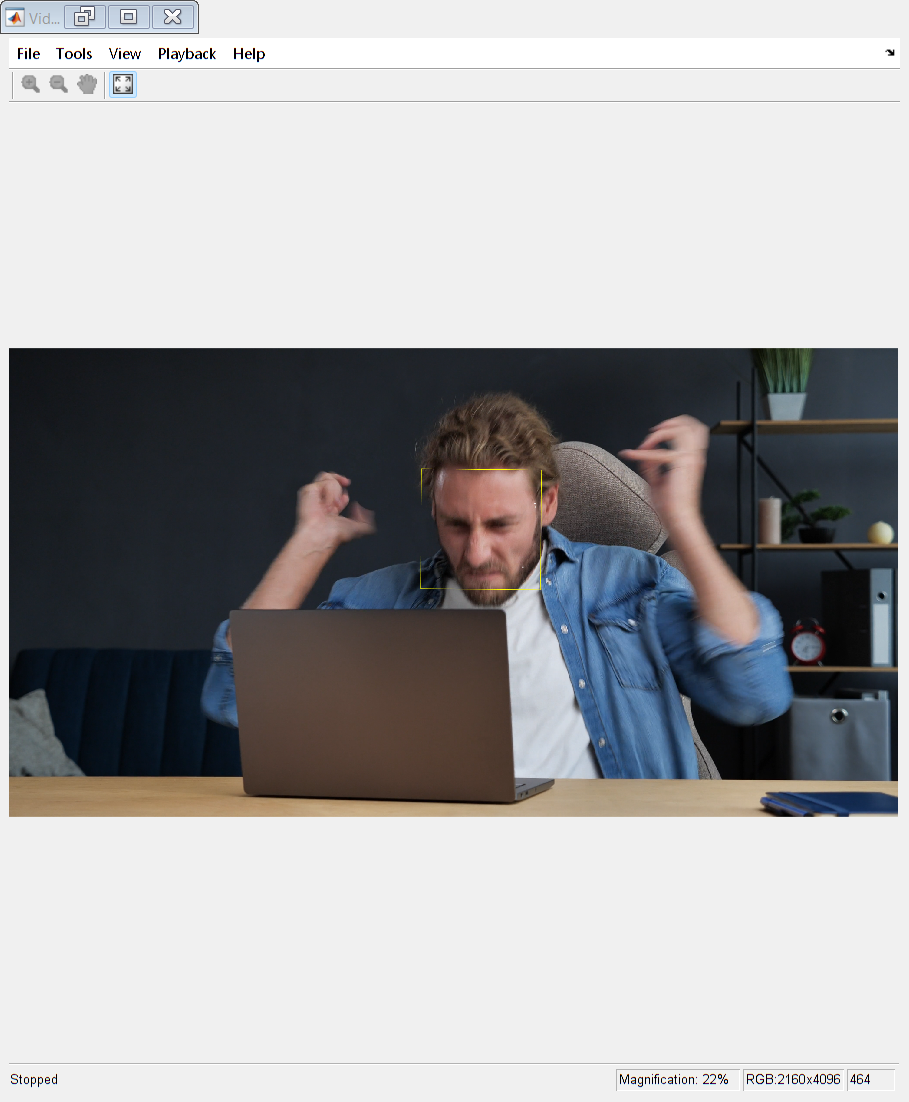

the_video= VideoReader("5125919-uhd_4096_2160_30fps.mp4");
video_frame=readFrame(the_video);

face_detector = vision.CascadeObjectDetector();
location_of_the_face=step(face_detector, video_frame);

detected_frame=insertShape(video_frame,"rectangle",location_of_the_face);

rectangle_to_points=bbox2points(location_of_the_face(1,:));
feature_points=detectMinEigenFeatures(rgb2gray(detected_frame), "ROI",location_of_the_face);

pointTracker = vision.PointTracker('MaxBidirectionalError',2);

feature_points=feature_points.Location;
initialize(pointTracker, feature_points,detected_frame);

left=100;
bottom=100;
width=size(detected_frame, 2);
height=size(detected_frame, 1);
video_player = vision.VideoPlayer('Position', [left bottom width height]);

previous_points=feature_points;

while hasFrame(the_video)

    video_frame = readFrame(the_video);
    [feature_points, isFound] = step(pointTracker, video_frame);
    new_points = feature_points(isFound, :);
    old_points = previous_points(isFound,:);

    if size(new_points, 1) >= 2
       [transformed_rectangle, old_points, new_points] = ...
           estimateGeometricTransform(old_points, new_points, ...
           'similarity' , 'MaxDistance', 4);
       rectangle_to_points = transformPointsForward(transformed_rectangle, rectangle_to_points);

       reshaped_rectangle = reshape(rectangle_to_points', 1,[]);
       detected_frame = insertShape(video_frame,"polygon", reshaped_rectangle, "LineWidth",2);

       detected_frame = insertMarker(detected_frame, new_points, '+', 'Color', 'White');

       previous_points=new_points;
       setPoints(pointTracker, previous_points);
    end
    step(video_player, detected_frame)

end

release(video_player);